# Relatório - Atividade 3 - Reguladores Autoajustáveis Determinísticos 

Análise e Projeto de Sistemas de Controle - 21.1

Prof. Antonio Marcus Nogueira Lima, Dr.

Aluno: Arthur Dimitri Brito Oliveira

Este relatório tem como objetivo a apresentação e o desenvolvimento dos exercícios resolvidos referentes a STR (*Self Tuning Regulators*) do Capítulo 3 do livro Adaptive Control [1]. 

## **Fundamentação Teórica**

A utilização de reguladores autoajustáveis (STR) está associada à automatização das tarefas envolvidas no desenvolvimento de sistemas de controle, como modelagem, projeto da lei de controle, implementação e validação. Nesse contexto, uma das razões para utilizar controladores adaptativos é que o processo ou o ambiente que o cerca mudam de forma contínua. 

Supondo um processo descrito por um sistema de única entrada e única saída


$$Ay(t) = B(u(t) + v(t))
$$


Sendo $y
$ a saída, $y$ a saída e $v
$ a perturbação. $A$ e $B$ são polinômios em função do operador de atraso $q^{-1}
$. Os graus dos polinômios são $deg\:A = n$ e $deb \: B = deg \:A - d_0$, sendo $d_0$ denominado de excesso de polo, e represente a parte inteira da razão entre o modelo do processo e o operador de atrado $q^{ -1} $.  

Uma lei de controle genérica pode ser descrita por: 


$$Ru(t) = Tu_c(t) - Sy(t)$$


Sendo $R, S$ e $T$ polinômios. Ao isolar $u(t)$ e substituir na equação do processo, tem-se:


$$u(t) = \frac{T}{R}u_c(t) - \frac{S}{R}y(t)$$



$$Ay(t) = B(\frac{T}{R}u_c(t) - \frac{S}{R}y(t) + v(t))$$



$$y(t)(\frac{AR + BS}{R})  =  B(\frac{T}{R}u_c(t) + v(t))$$



$$y(t) = \frac{BT}{AR + BS}u_c(t) + \frac{BR}{AR + BS}v(t)$$



$$u(t) = \frac{AT}{AR + BS}u_c(t) - \frac{BS}{AR+BS}v(t)$$


O polinômio característico da malha fechada é, então:


$$A_c = AR + BS$$


A ideia central do método de projeto é a especificação de um polinômio característico desejado. A equação anterior é conhecida como **Equação Diophantina.  **No entanto, a equação só determina os polinômios $R
$ e $S$, o que requer outras condições para determinar o polinômio $T$. Avaliando a resposta do sinal de controle $u_c$ para a saída, descrita pelas dinâmicas:


$$A_my_m(t) = B_mu_c(t)$$



$$\frac{BT}{AR + BS}  = \frac{BT}{A_c} = \frac{B_m}{A_m}$$


O polinômio $B$ pode ser escrito como $B = B^+B^-$, onde $B^+$ é um polinômio mônico, cujos zeros são estáveis e bem amortecidos, de maneira que podem ser cancelados pelo controlador. $B^-$ corresponde a fatores instáveis ou pouco amortecidos que não podem ser cancelados. Assim, $B^-$ deve ser um fator de $B_m$, de modo que:


$$B_m = B^- B_m'$$


$A_m$ também deve ser um fator de $A_c$, de modo que:$A_c = A_0A_mB^+$. Assim:


$$\frac{B^+B^-T}{A_0A_mB^+} = \frac{B^-B_m'}{A_m}$$



$$T = A_0B_m'$$


De tal forma que a equação de Diophantine se torna


$$AR' + B^-S = A_0A_m = A_c'$$


## Desenvolvimento 

Os métodos aqui descritos foram implementados utilizando o Matlab. Inicialmente, os problemas referentes aos exemplos são formulados. Posteriormente, discute-se a resolução e os resultados obtidos com as simulações. 

***Exemplo 3.1: Cancelamento de zeros***

Considerando um processo de tempo contínuo descrito por: 


$$G(s) = \frac{1}{s(s+1)}$$


A função de tempo discreto para $h=0.5$ é:


$$H(q) = \frac{B(q)}{A(q)} = \frac{b_0q + b_1}{q^2 + a_1q + a_2} = \frac{0.1065q + 0.0902}{q^2 - 1.6065q + 0.6065}$$


Tendo o sistema desejado em malha-fechada sendo:


$$\frac{B_m(q)}{A_m(q)} = \frac{b_{m0}q}{q^2 + a_{m1}q + a_{m2}} = \frac{0.1761q}{q}2 - 1.3205q + 0.4966}$$


Pelo algoritmo MDPP, sabe-se que $B^-=b_0$, $B^+ = B/b_0$, $B_m = B_m'B^-$, assim:


$$B^+= \frac{b_0q+b1}{b_0} = q + b_1/b_0$$



$$B^- = b_0$$



$$B_m' = b_{m0}q/b_0$$


O processo é de segunda ordem, isto implica que os polinômios $R,S \:\:e\:\:T$ seraõ de primeira ordem, já que $degS = degA - 1$, $degR = degS = 1$. Então $degR' = degR-degB^+ $, no entanto, como o polinômio é monico, $R' =1$. Como $degA_0 = degA - degB  - 1=0$, $A_0 = 1$. A equação de Diophantine se torna: 


$$AR' + B^- S = (q^2 + a_{1}q + a_{2}).1 + b_0(s_0q + s_1)  = q^2 + a_{m1} + a_{m2}$$


Comparando os coeficientes, tem-se:


$$s_0 = \frac{a_{m1}-a_1}{b_0}$$



$$s_1 = \frac{a_{m2} - a_2}{b_0}$$


Diante disso, conclui-se que:


$$R = B^+R' = B^+ = q + b_1/b_0$$



$$S = s_0q + s_1 = \frac{a_{m1} - a_1}{b_0}q + \frac{a_{m2}-a_2}{b_0}$$



$$B_m' = \frac{b_{m0}q}{b_0}$$


Para que as dinâmicas indesejáveis referentes ao fator $B^+$ sejam canceladas pelo polinômio característico do controlador $A_c$, é necessário que o zero não seja pouco amortecido. 

***Exemplo 3.2: Model-following sem cancelamento de zeros***

Considerando o mesmo equivalente discreto para a função de transferência $G(s)$:


$$H(q) = \frac{b_0q + b_1}{q^2 + a_1q + a_}$$


Como não há o cancelamento de nenhum zero, pode-se afirmar que:


$$B^+ = 1$$



$$B = B^+B^- = B^- = b_0q+b_1$$


Tendo em vista a resposta desejada em malha fechada como sendo: 


$$H_m(q) = \beta\frac{b_0q + b_1}{q^2 + a_{m1}q + a_{m2}}= \frac{b_{m0}q + b_{m1}}{q^2 + a_{m1}q + a_{m2}}$$


$\beta$ é responsável pelo ganho unitário em regime. Sabendo que $degS= degA - 1= 1$, $degR'=degR-degB^+ =1$, de modo que $R'$ é monico e equivale a $R' = q + r_1$. Como $degS =  1$, $s=s_0q+s_1$. A equação de Diophantine então se torna:


$$AR' + B^- S = (q^2 + a_{1}q + a_{2})(q+r_1) + (b_0q + b_1)(s_0q + s_1)$$


Ao adotar-se $q=-b_1/b_0$:


$$r_1 = \frac{a_0a_{m2}b_0^2 +(a_2-a_{m2}-a_0a_{m1})b_0b_1 + (a_0 + a_{m1} - a_1)b_1^2}{b_1^2 - a_1b_0b_1 + a_2b_0^2}$$


Vale-se salientar que o denominador de $r_1$ é nulo caso A e B tenham um fator em comum. No entanto, caso isso aconteça, a premissa da equação de Diophantine de que A e B são primos relativos é invalidada. 

***Exemplo 3.3: Sistema de tempo contínuo***

O método proposto no exemplo 1 será usado para determinar um controlador de tempo contínuo. Tendo em vista que o processo é de segunda ordem, o sistema em malha fechada será de terceira ordem. A função de transferência é:


$$G(s) = \frac{b}{s(s + a)}$$


Como $degA = 2$ e $deg B= 1$, sabe-se que $B^-=b$, $B = B^+B^- \rightarrow B^+ = B/B^-=1$. Sabendo que a resposta desejada para a função de transferência é:


$$\frac{B_m(s)}{A_m(s)} = \frac{w^2}{s^2 + 2\xi \omega s + w^2}$$


Sabendo que $B_m = B_m'B^- \rightarrow Bm'=\omega^2/b$, e que $deg S = degA - 1 = 1$ e $degS = degR = 1$, tem-se que $R'$ é monico. Além disso, $degA_0 = degA-degB^+ -1 = 1$, de modo que $A_0 = s + a_0$. Por fim, $degS = 1 \rightarrow S = s_0s + s_1$. A equação de Diophantine se torna:


$$AR' + B^- S = s(s+a)(s+r_1) + b(s_0s+s_1) = (s^2 + 2\xi \omega s + \omega^2)(s+a_0)$$


Igualando os termos, tem-se:


$$a + r_1 = 2\xi\omega + a_0$$



$$ar_1 + bs_0 = w^2 + 2\xi \omega a_0$$



$$bs_1 = w^2a_0$$


Caso $b\neq0$, a solução das equações é:


$$r_1 = 2\xi\omega + a_0 - a$$



$$s_0 = \frac{a_02\xi\omega + w^2 - ar_1}{b}$$



$$s_1 = \frac{\omega^2a_0}{b}$$


Sabendo que $B^+ = 1$, $B^- = b$ e que $B_m'=\omega^2/b$, tem-se que:


$$T(s) = B_m'(s)A_0(s) = \frac{\omega^2}{b}(s+a_0)$$


É possível dar uma interpretação ao polinômio $A_0$ que aparece na solução de grau mínimo da alocação de polos no caso em que nenhum zero do processo é cancelado, ou seja, quando $B^- \neq b_0$. A equação de Diophantine se torna:


$$\frac{T}{R} = \frac{A_0B_m'}{R} = \frac{(AR'+BS)B_m'}{A_mR}=\frac{AB_m}{BA_m} + \frac{SB_m}{RA_m}$$


A lei de controle pode ser escrita como:


$$u = \frac{T}{R}u_c - \frac{S}{R}y = \frac{AB_m}{RA_m}u_c -\frac{S}{R}y = \frac{AB_m}{BA_m}u_c-\frac{S}{R}(y-y_m)$$


Um diagrama de blocos que representa este controlador pode ser observado na Figura 1. Ele pode ser interpretado como a combinação de um controlador *feedforward, *que tenta cancelar as dinâmicas da planta e substituir pela dinâmica  desejada $B_m/A_m$, e por um controlador de realimentação, que tenta fazer com que a saída siga tal modelo. 

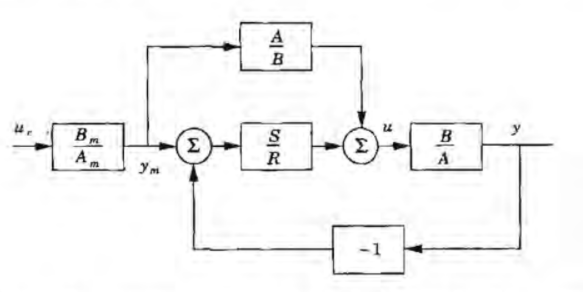

**Figura 1: **Representação alternativa do diagrama de blocos para o seguidor de modelo. 

 Sabendo que $degB < degA$, é evidente que $\frac{A}{B}$ não é realizável. Caso o sistema seja fase-mínima, $A/B$ será instável. No entanto, a combinação do modelo desejado $B_m/A_m$ e $A/B$ é realizável se:


$$degS \leq degR$$



$$degT\leq degR$$


Vale-se salientar que a concatenação resultante, $\frac{AB_m}{BA_m}$ , está separada de $S/R$, e estes termos podem causar quaisquer problemas de instabilidade pois eles aparecem apenas como parte do compensador *feedforward. *

***Exemplo 3.4: Regulador auto-ajustável com cancelamento de zero do processo***

Caso a função de transferência do processo não seja conhecida, é possível utilizar o método de mínimos quadrados recursivo para estimá-la. Sendo o modelo do processo descrito por: 


$$y(t) = -a_1y(t-1) - a_2y(t-2) - \:\: ... \:\:-a_ny(t-n) + b_0u(t-d_0 + \:\:...\:\:b_mu(t-d_0-m)$$


O modelo pode ser expresso como: 


$$y(t) = \varphi^T(t-1)\theta$$


Sendo $\theta^T = [a_1 \:\: a_2 \:\: ... \:\: a_n \:\: b_0 \:\: b_m]$, $\varphi^T(t-1) = [-y(t-1) \:\: ... \:\: -y(t-n) \:\: u(t-d_o) \:\: u(t-d_0-m)]$. O estimador é expresso por: 


$$\hat \theta(t) = \tilde\theta(t-1) + K(t)\epsilon(t)$$



$$\epsilon(t) = y(t) - \varphi^T(t-1)\hat\theta(t-1)$$



$$K(t) = P(t-1)\varphi(t-1)(\lambda + \phi^T(t-1)P(t-1)\varphi(t-1))^{-1}$$



$$P(t) = (I - K(t)\varphi^T(t-1))P(t-1)/\lambda$$


A estimação dos coeficientes associados à função de transferência ocorre e aplica-se a equação de Diophantine para atingir o desempenho desejado em malha fechada. Este procedimento ocorre a cada instante de amostragem.

A função de transferência desejada para a malha fechada é dada por:

 
$$H_m(q) = \frac{0.1761q}{q^2-1.3205+0.4966}$$


O comportamento temporal desejado, a resposta temporal alcançada e o sinal de controle aplicado podem ser visualizados na Figura (XXXXXXXXXXXX) a seguir:

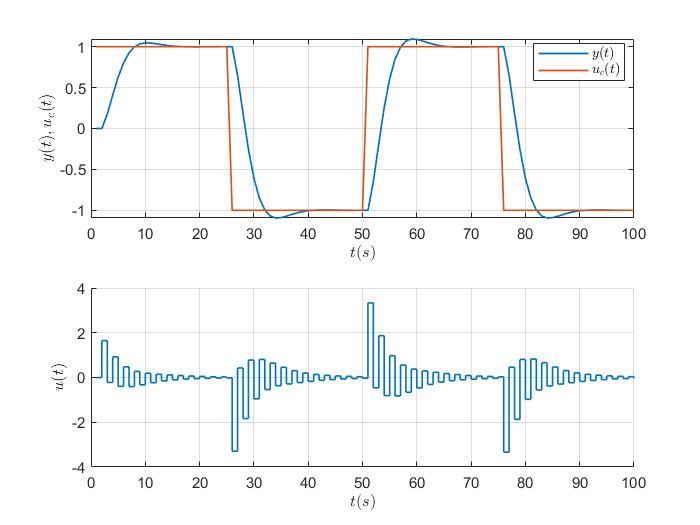

ex_4

**Figura 2: **Resposta temporal do sinal de saída $y(t)$, a referência adotada $u_c(t)$ e o sinal de controle aplicado $u(t)$. 

Os parâmetros do controlador são expressos como funções dos parâmetros do modelo e das especificações, de modo que:


$$u(t) = r_1u(t-1) = t_0u_c(t) - s_0y(t) - s_1y(t-1)$$


Pela resposta temporal, é evidente que o sinal de controle tem severas oscilações. Isso se deve ao zero pouco amortecido $z=b_1/b_0=-0.85$. Considerando que a função de transferência associada à resposta temporal de $y(t)$ pode ser descrita por: 


$$H(q) = \frac{b_0q + b_1}{q^2 + a_1q + a_2}$$


Ao estimar os parâmetros dos polinômios característicos por meio do método de mínimos quadrados recursivo, tem-se a estimativa dos parâmetros em função do tempo na figura a seguir.

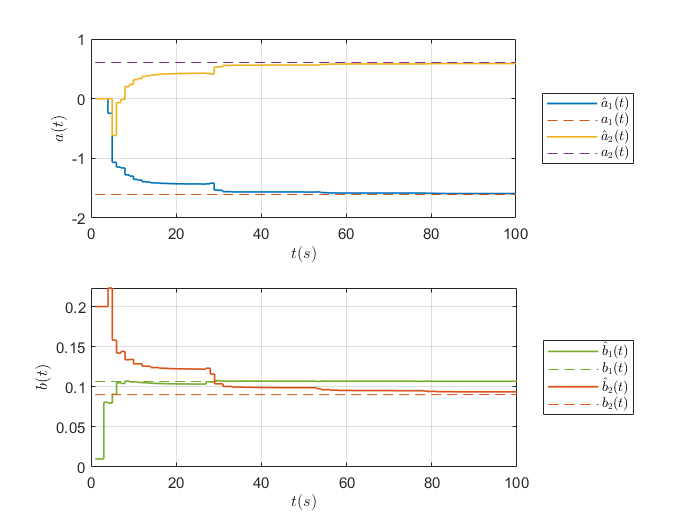

ex_4_2

**Figura 3: **Evolução temporal da estimativa dos parâmetros $\hat b_0$, $\hat b_1$, $\hat a_1$ e $\hat a_2$ da função de transferência $H(q).$

Como pode-se observar, há uma boa aproximação dos parâmetros reais do processo, em malha aberta, após 25 segundos de simulação. Os polinômios $R, S\:\:e\:\:T$ do controlador desejado também são calculados. Sua convergência para os valores desejados pode ser visualizada a seguir: 

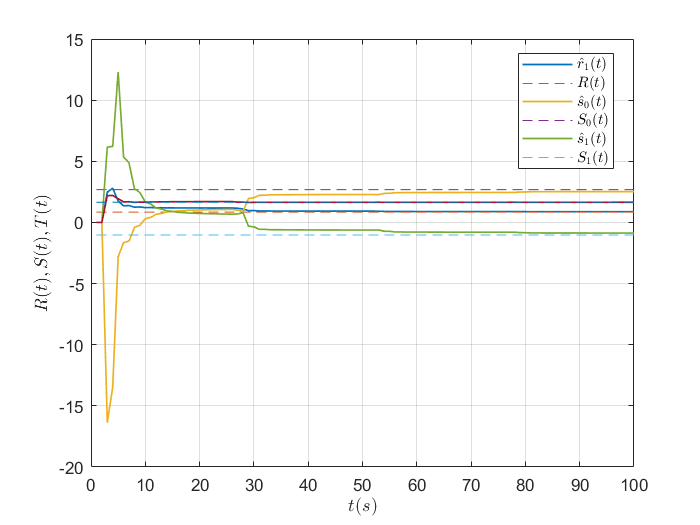

ex_4_3

**Figura 4: **Evolução temporal da estimativa dos coeficientes polinomiais $R, S \:\: e \:\:T$. 

Como pode-se observar, a estimação dos coeficientes polinomiais converge para os valores desejados. Caso deseje-se uma maior suavidade no sinal de controle aplicado, pode-se manter o zero do processo. 

***Exemplo 3.5: Regulador indireto auto-ajustável sem cancelamento do zero do processo***

A função que expressa o desempenho em malha fechada é dada por: 


$$H_m(q) = \frac{B_m}{A_m} = \frac{0.0953q + 0.0808}{q^2-1.3205q+0.4966}$$


O resultado da simulação pode ser visualizado na Figura 5.

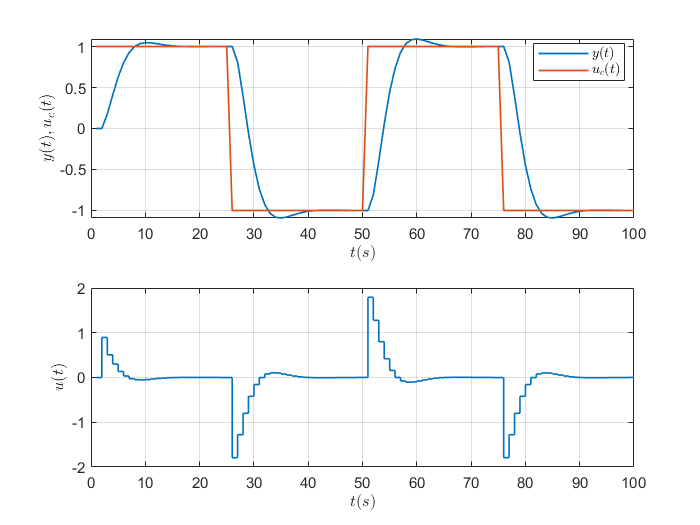

ex_5

**Figura 5: **Sinais de saída $y(t)
$, referência $u_c(t)$ e de controle $u(t).$

Pode-se observar um sinal de controle mais suave, e isso se dá pela permanência dos zeros pouco amortecidos do processo. A estimativa dos parâmetros $\hat \theta$ por meio de RLS pode ser visualizada na Figura 6.

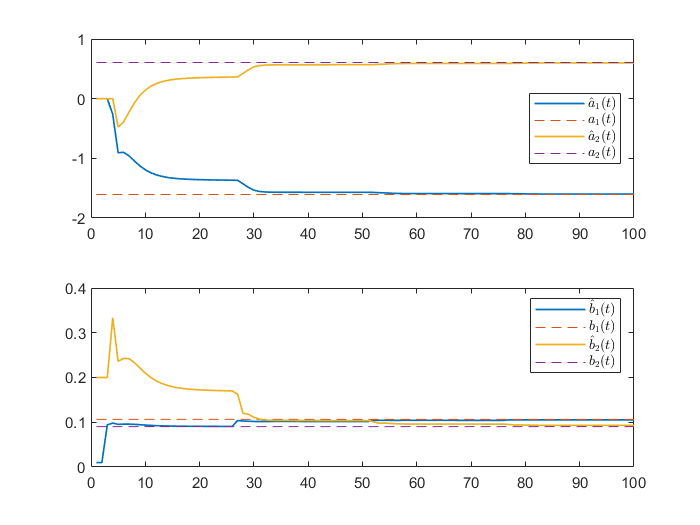

ex_5_1

**Figura 6: **Evolução temporal da estimativa dos parâmetros $\hat \theta$.

A estimação dos parâmetros claramente converge para os valores reais esperados. Também estima-se os polinômios do controlador, e estes podem ser observados na Figura 7.

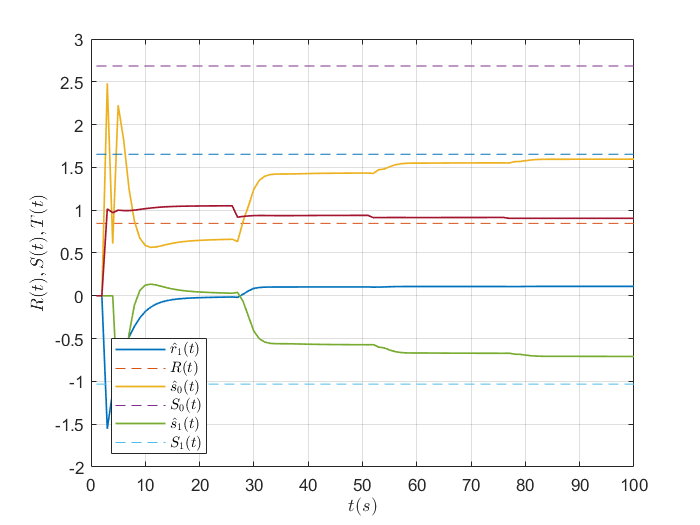

ex_4_3

**Figura 6: **Evolução temporal da estimativa dos polinômios $R, S\:\: e \:\: T$.

***Exemplo 3.6: Regulador indireto auto-ajustável sem cancelamento do zero do processo***

Considerando a função de transferência do processo como sendo

$G(s) = \frac{1}{s^2+s}$ e uma função de transferência em malha-fechada da forma $G_m(s) = \frac{\omega^2 }{s^2 + 2\xi\omega s + \omega^2}$. Para definir $B^+ = 1$, faz-se necessário que $A_0 = q+a_0$, com $a_0 = 2$.  O sinal de referência $u_c(t)$,  o sinal de saída $y(t)$ e o sinal de controle $u(t)$ podem ser visualizados na Figura 7. 

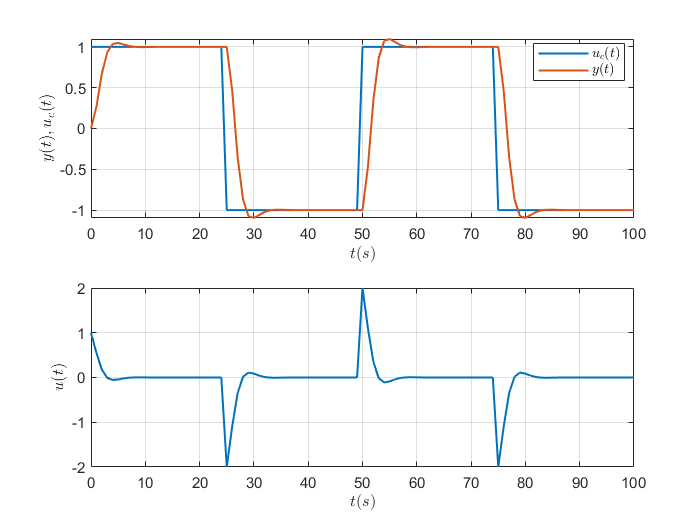

ex_6_1

**Figura 7: **Sinais de saída $y(t)
$, referência $u_c(t)$ e de controle $u(t).$

E estimação dos parâmetros da função de transferência para o processo por meio de RLS resulta em: 

ex_6_2

Gc =
 
    -0.05287 s + 0.8252
  ------------------------
  s^2 + 1.363 s + 0.002261
 
Continuous-time transfer function.



Como pode-se observar, o numerador da função de transferência não corresponde à função de transferência desejada para a malha-fechada. Esse erro numérico pode ser associado à conversão do domínio discreto para o contínuo. A resposta temporal comparativa entre $y_m(t)$ e $y(t)$ ilustrada na Figura 8 evidencia o erro supramencionado. 

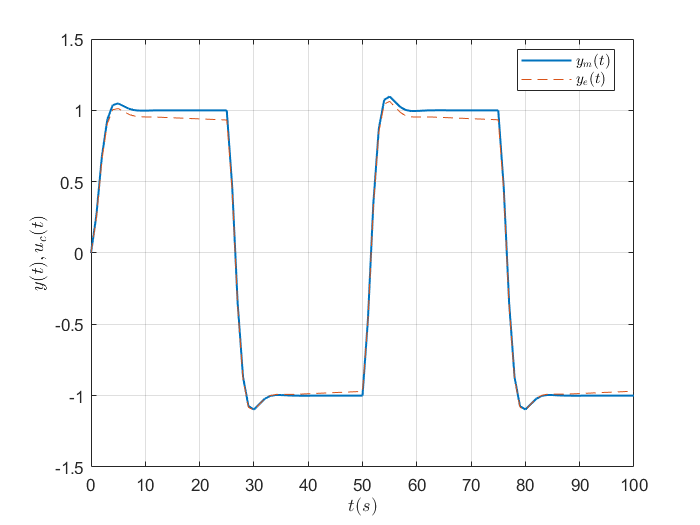

ex_6_3

**Figura 8: **Sinal de saída desejado $y(_mt)
$ e sinal de saída real $y(t)$.

mse(y,ym)

ans = 0.0013

***Exemplo 3.7: Regulador auto-ajustável direto***

Ao multiplicar ambos os lados da equação de Diophantine por $y(t)$tem-se:


$$A_0A_my(t) = AR'y(t) + B^- Sy(t)$$


Considerando $Ay(t) = Bu(t)$ e $R'B = RB^- $, tem-se:


$$A_0A_my(t) = B^- (Ru(t) + Sy(t))$$


Esta equação pode ser considerada um modelo do processo parametrizada pelos coeficientes polinomiais $B^-, R \:\:e \:\:S$. Se os parâmetros desta equação são estimados, a lei de controle é então obtida diretamente, sem projeto. O modelo da equação anterior é não-linear quanto aos parâmetros pois o lado direito da igualdade é multiplicado por $B^-$. 

Caso as dinâmicas do processo o configurem como um sistema de fase mínima, $degA_0 = degA - degB - 1$, $B^-
$ será simplesmente uma constantee e a equação se torna:


$$A_mA_0y(t) = b_0(Ru(t)+Sy(t)) = \tilde Ru(t) + \tilde Sy(t)$$


Onde $R$ é monico e $\tilde R = b_0R$ e $\tilde S = b_0S$. O vetor de parâmetros pode ser definido como:


$$\theta = [r_0 \:\:... \:\:r_i\:\:s_0 \:\: ... \:\: s_i]$$


Por sua vez, o vetor de regressão é:


$$\varphi(t) = [u(t) \:\: ... \:\: u(t-l) \:\: y(t) \:\: ... \:\: y(t-l)]$$


No caso deste exemplo, como $degA = 2$ e $degB=1$, $degA_m=2$ e $degA_0=0$, de modo que $A_0=1$. Desse modo, o modelo é descrito por:


$$y(t) = r_0u_f(t-1)+r_1u_f(t-2) + s_0y_f(t-1) + s_1y_f(t-2)$$


As estimativas dos coeficientes dos polinômios $R, S \:\:e \:\: T$ podem ser observadas na Figura 9. 

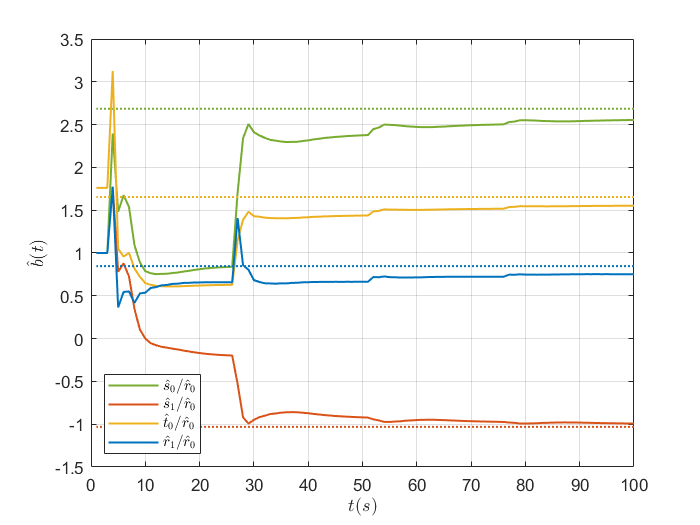

ex_7

**Figura 9: **Evolução temporal da estimativa dos coeficientes polinomiais R, S e T do controlador.

***Exemplo 3.8: Regulador direto com d0=2***

A partir da derivação do algoritmo direto, o parâmetro $d_0$ era o excesso de polos da planta. Inicialmente, não sabe-se o valor de $d_0$ e este é tratado como um parâmetro. Por padrão de projeto $d_0=2$ e mantendo $A_0=1$. Em malha fechada, a estimação se torna:


$$y(t) = r_0u(t-2) + r_1u(t-3) + s_0y(t-2) + s_1(t-3)$$


A divisão dos parâmetros por $\hat r_0$ também é necessária já para que os polinômios $\tilde R \:\:e\:\:\tilde S$ sejam transformados em $R \:\: e \:\: S$, visto que $B^-=b_0$. As estimativas dos polinômios $\hat s_0/\hat r_0$, $\hat s_1/ \hat r_0$, $\hat t_0/ \hat r_0$ e $\hat r_1/\hat r_0$ podem ser visualizadas na figura abaixo. 

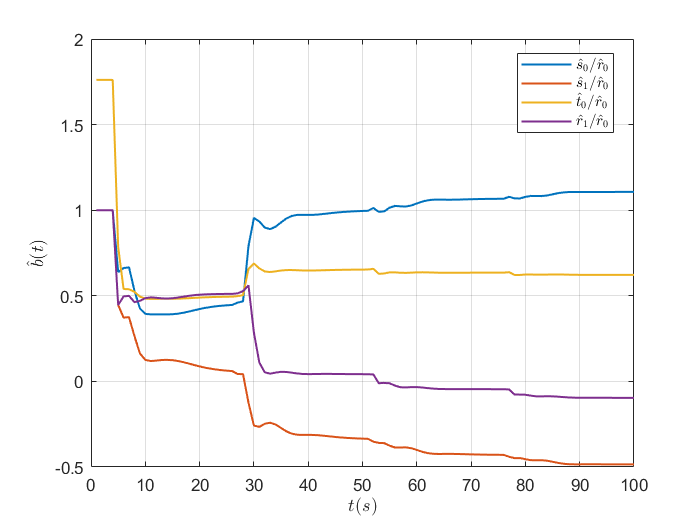

ex_8

**Figura 10: **Evolução temporal da estimativa dos coeficientes polinomiais R, S e T do controlador.

***Exemplo 3.9: Efeito de perturbações***

Considerando o sistema do exemplo 5, onde há a regulação autoajustável indireta sem cancelamento de zeros. Adciona-se um ruído da forma $v(t) = 0.5$ para $t >= 40$. O comportamento do sistema em termos da saída $y(t)$, do sinal de controle $u(t)$ e da referência imposta $u_c(t)$.

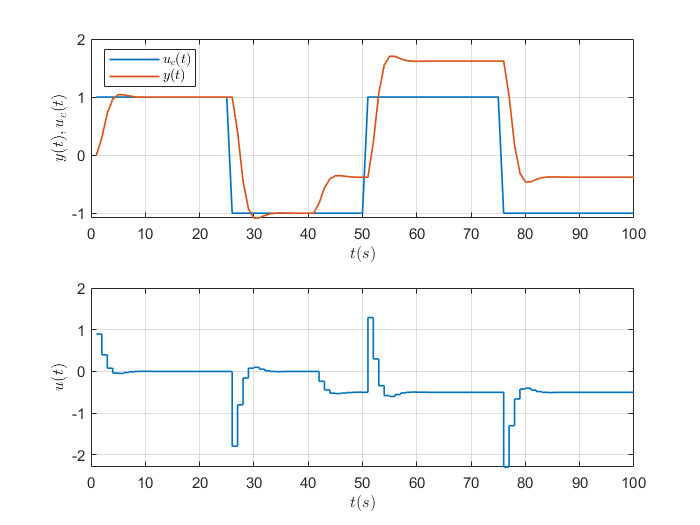

ex_9_1

**Figura 11: **Sinais de saída $y(t)
$, referência $u_c(t)$ e de controle $u(t).$

Como pode-se observar, a adição do distúrbio conduz a um erro em regime permanente. Para estimar os parâmetros por meio da técnica recursiva de mínimos quadrados, utilizou-se um fator de esquecimento $\lambda = 0.98$. A estimativa pode ser visualizada na Figura abaixo. 

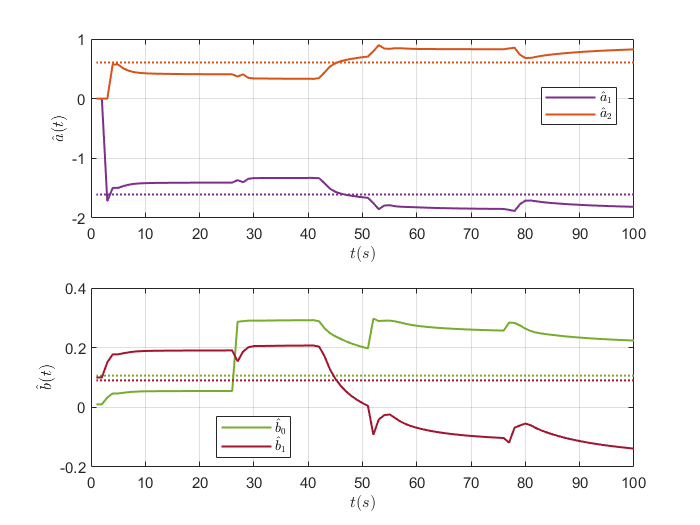

ex_9_2

**Figura 12: **Evolução temporal da estimação dos parâmetros $\hat \theta$ do processo. 

Observa-se que há mudanças rápidas na estimação dos parâmetros sempre que há uma mudança no sinal de controle. E isto também é constatável após a adição da  perturbação a partir de $t=40s$. Estes erros na estimação podem indicar que a estrutura do modelo não está correta. Quando o sinal de controle se torna constante, os parâmetros tendem à estabilização em valores distantes dos parâmetros esperados. 

Para lidar com esse tipo de perturbação, pode-se adicionar um modelo dela, caso conhecido. Além disso, é possível adicionar um filtro que atenue as perturbações presentes no processo. 

### Prova dos teoremas 9.4.1 e 9.4.2

#### Teorema 9.4.1

O erro da estimação de estado $\tilde x = \hat x- x $ é inatingível a partir da entrada de referência $v$.

Considerando um sistema do tipo:

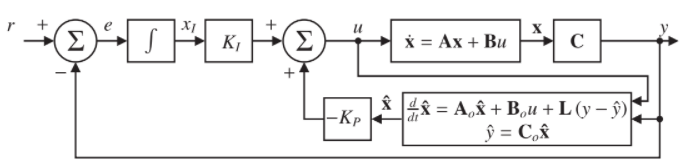


$$\rho x = Ax + Bu$$



$$y=Cx$$


O observador de estados pode então ser definido como:


$$\rho \hat x = A \hat x+ Bu + J(y-C\hat x)$$



$$\hat y = C\hat x$$


A diferença entre os valores reais e estimados pode ser expresso por:


$$\rho \tilde x = \rho x - \rho \hat x$$



$$\rho \tilde x = A(x-\hat x)- J(Cx-C\hat x)$$



$$\rho \tilde x= (A-JC)(x-\hat x)$$


O sinal de controle é então:


$$u = -K_p \hat x+K_iX_i = -K_p(x-\tilde x) + K_ix_i$$


A partir do diagrama, pode-se definir:


$$\dot x_i = e = r-y = r -Cx_i$$



$$\dot x = Ax + B(-k_p\hat x + k_ix_i) = Ax - Bk_p(x-\tilde x) + Bk_ix_i \rightarrow \dot x = (A-Bk_p)x + Bk_p\tilde x + Bk_ix_i  $$



$$\tilde \dot x = \dot x - \hat \dot x = Ax + Bu - A\hat x - Bu - L(y-\hat y) = (A-LC)\tilde x$$



$$u = -(k_ix_i + k_px - k_p\tilde x)$$



$$\left[\matrix{ \dot x_i \cr \dot x \cr \dot \tilde x} \right] = \left[\matrix{0 & -C & 0 \cr BK_i & A-Bk_p & Bk_p \cr 0 & 0 & A-LC}\right ]  \left[\matrix{x_i \cr x \cr \tilde x}\right ]  +  \left[\matrix{1 \cr 0 \cr 0}\right ]r$$



$$u =  \left[\matrix{-k_i & k_p -k_p}\right ]  \left[\matrix{x_i \cr x \cr \tilde x}\right ] $$



$$y =  \left[\matrix{0 & C & 0}\right ]  \left[\matrix{x_i \cr x \cr \tilde x}\right ] $$


O observador, a partir da definição de $E_1$ como o polinômio característico de $A-JC$ e $E_2$ como $(A-BK)$, assim $\rho \hat x = (A-JC)\hat x + Bu + Jy$ pode ser reescrita como:


$$E_1(\rho) \hat x = V_1(\rho)u + V_2(\rho)y$$


Onde:


$$V_1(\rho) = Adj[\rho I-A+JC]^{-1}B$$



$$V_2(\rho) = Adj[\rho I-A+JC]^{-1}J$$



$$E_1(\rho) = det[\rho I - A + JC]$$


Sendo a lei de realimentação para estimação dada por $u = -K\hat x+k_ix_i$, substituindo as expressões anteriores, tem-se:


$$u = -K \left [\frac{V_1(\rho)}{E_1(\rho)}u+\frac{V_2(\rho)}{E_1(\rho)y}\right]+k_ix_i$$


Definindo:


$$P(\rho) = KV_2(\rho)$$



$$L(\rho) = E_1(\rho)+KV_1(\rho)$$


Assim:


$$V_1(\rho) = E_1(\rho)[\rho I-A+JC]^{-1}B$$



$$V_2(\rho) = E_1(\rho)[\rho I-A+JC]^{-1}J$$


Expressando de forma compacta o observador e a estimação do estado:


$$\frac{L}{E_1}u = -\frac{P}{E_1}y + v$$


Os operadores $L \:\: e \:\:P$ satisfazem a seguinte identidade polinomial:


$$DL+NP = E_1E_2$$


Usando as informações anteriores, tem-se:


$$L(\rho)D(\rho)+P(\rho)N(\rho) = D(\rho){[E_q(\rho) + K[V_1(\rho) + V_2(\rho)C(\rho I-IA)^{-1} B]]$$



$$= D(\rho)E_1(\rho){1+K(\rho I - A + JC)^{-1} B + K(\rho I - A + JC)}^{-1}xJC(\rho I - A)^{-1}B]$$


=$D(\rho)E_1(\rho)[1+K(\rho I - A + JC)^{-1}[(\rho I - A)+JC](\rho I - A)^{-1}B]$


$$= D(\rho)E_1(\rho)[1+K(\rho I - A)^{-1} B]$$



$$=D(\rho)E_1(\rho)det[I+(\rho I-A)^{-1} BK]$$



$$= D(\rho)E_1(\rho)det[(\rho I-A)^{-1}]det[\rho I - A + BK]$$


Sabendo que $D(\rho) = det(\rho I - A)$ e que $E_2(\rho) = det(\rho I - A + BK)$, tem-se:


$$L(\rho)D(\rho) + P(\rho)N(\rho) = E_1(\rho) E_2(\rho)$$


$v $ é escolhido na forma:


$$v = \frac{G}{E_1}y^*$$


Nesse caso, a realização mínima da lei de controle é dada por:


$$Lu = -Py + Gy^*$$


## Referências bibliográficas 

[1] K. ASTRÖM, B. WITTENMARK.** Adaptive Control**. CRC Press, 2000. ISBN 0486462781